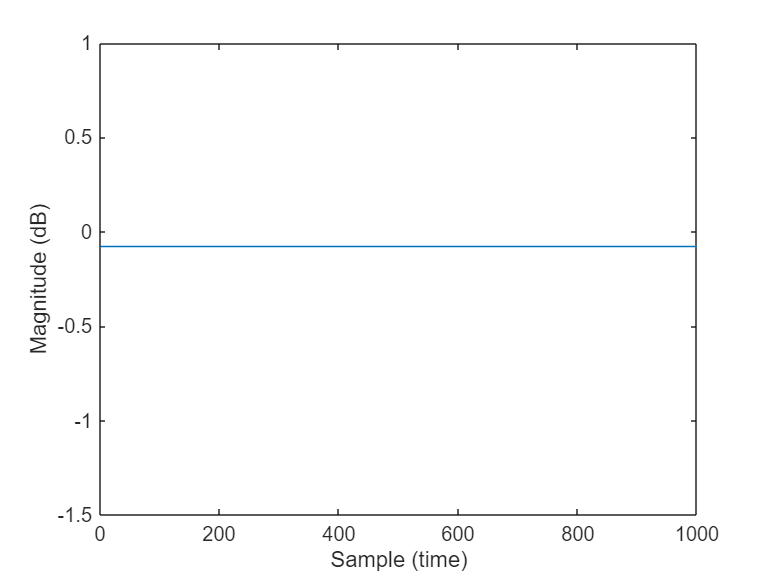

% Create the TDL channel object
tdl = nrTDLChannel;

tdl.DelayProfile = 'Custom';          % Use a custom profile
tdl.NumTransmitAntennas = 1;          % Single Tx antenna
tdl.NumReceiveAntennas = 1;           % Single Rx antenna
tdl.SampleRate = 30.72e6;             % 30.72 MHz sample rate

tdl.MaximumDopplerShift = 0;          % No Doppler, static channel
tdl.PathDelays = 1e-6;                % Single path with 1 µs delay
tdl.AveragePathGains = 0;             % 0 dB gain (no attenuation)

% Generate input signal (random example)
signalIn = randn(1000,1);             % 1000 samples of random noise

% Pass signal through the channel
[signalOut, pathGains, sampleTimes] = tdl(signalIn);

% Plot the path gains in dB
plot(10*log10(abs(pathGains)));
xlabel('Sample (time)'); ylabel('Magnitude (dB)');

Change MaximumDopplerShift to have path gain change overtime

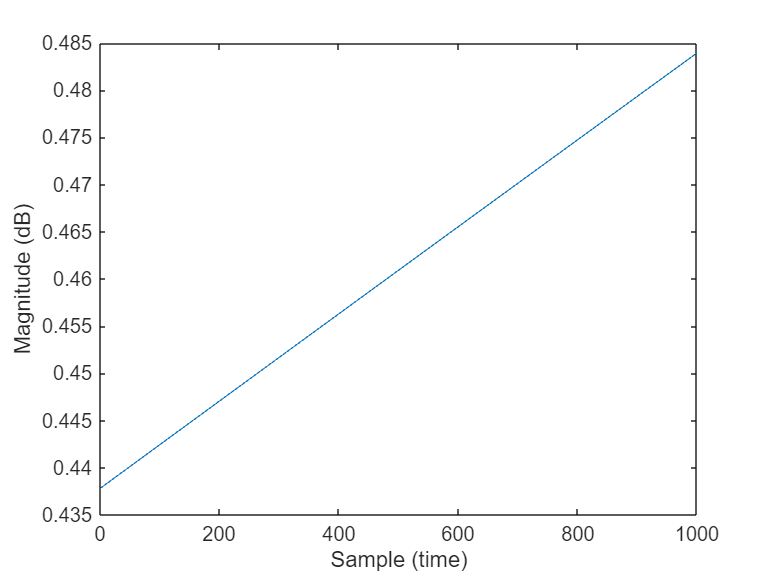

% Create the TDL channel object
tdl = nrTDLChannel;

tdl.DelayProfile = 'Custom';          
tdl.NumTransmitAntennas = 1;
tdl.NumReceiveAntennas = 1;
tdl.SampleRate = 30.72e6;             % 30.72 MHz

tdl.MaximumDopplerShift = 100;        % Doppler shift of 100 Hz (gain varies)
tdl.PathDelays = 1e-6;                % Single path with 1 µs delay
tdl.AveragePathGains = 0;             % Average gain of 0 dB (reference level)

% Generate input signal (random example)
signalIn = randn(1000,1);             % 1000 samples of random noise

% Pass signal through the channel
[signalOut, pathGains, sampleTimes] = tdl(signalIn);

% Plot the path gains in dB
plot(10*log10(abs(pathGains)));
xlabel('Sample (time)'); ylabel('Magnitude (dB)');

4 paths

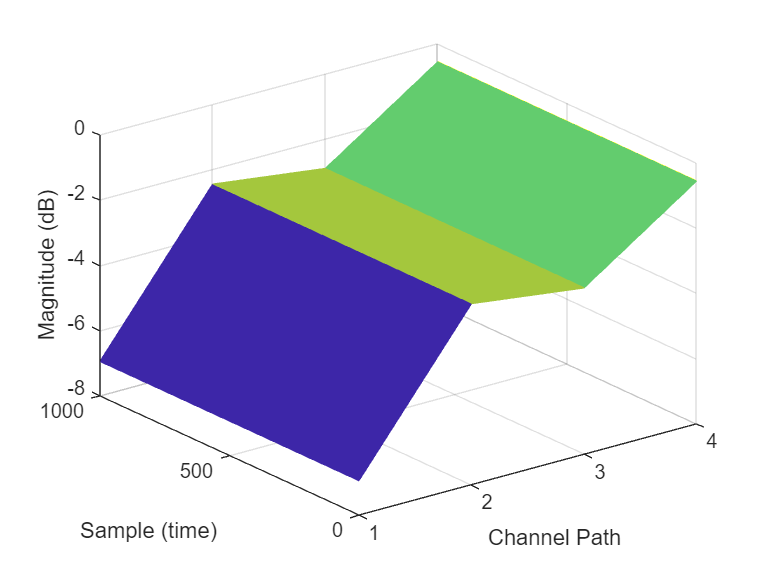

% Create the TDL channel object
tdl = nrTDLChannel;

tdl.DelayProfile = 'Custom';          
tdl.NumTransmitAntennas = 1;
tdl.NumReceiveAntennas = 1;
tdl.SampleRate = 30.72e6;             % 30.72 MHz

tdl.MaximumDopplerShift = 0;                    % No Doppler, static channel
tdl.PathDelays = [1e-6, 1e-6, 1e-6, 1e-6];      % 4 paths, all at 1 µs
tdl.AveragePathGains = [0, 0, 0, 0];            % Average gain of 0 dB (reference level)

% Generate input signal (random example)
signalIn = randn(1000,1);             % 1000 samples of random noise

% Pass signal through the channel
[signalOut, pathGains, sampleTimes] = tdl(signalIn);

% Plot the path gains in dB
mesh(10*log10(abs(pathGains)));
xlabel('Channel Path');
ylabel('Sample (time)'); zlabel('Magnitude (dB)');

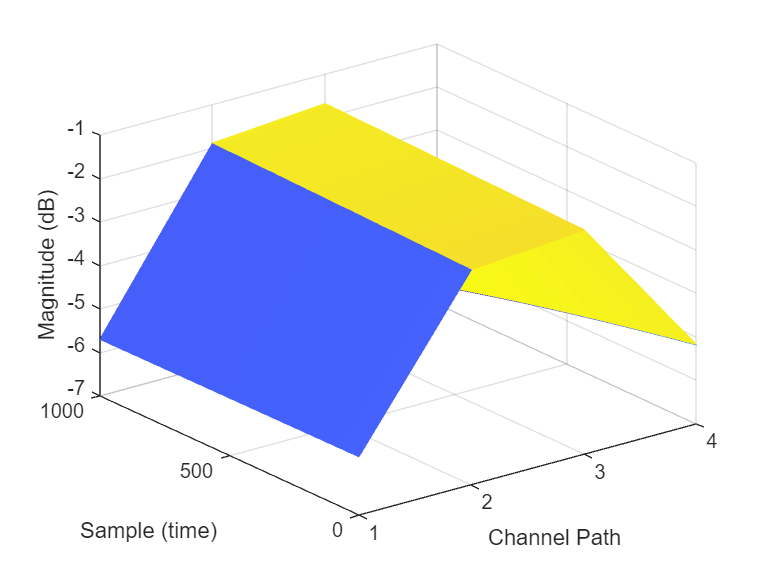

% Create the TDL channel object
tdl = nrTDLChannel;

tdl.DelayProfile = 'Custom';          
tdl.NumTransmitAntennas = 1;
tdl.NumReceiveAntennas = 1;
tdl.SampleRate = 30.72e6;             % 30.72 MHz

tdl.MaximumDopplerShift = 500;                  % Doppler shift of 100 Hz (gain varies)
tdl.PathDelays = [1e-6, 1e-6, 1e-6, 1e-6];      % 4 paths, all at 1 µs
tdl.AveragePathGains = [0, 0, 0, 0];            % Average gain of 0 dB (reference level)

% Generate input signal (random example)
signalIn = randn(1000,1);                       % 1000 samples of random noise

% Pass signal through the channel
[signalOut, pathGains, sampleTimes] = tdl(signalIn);

% Plot the path gains in dB
mesh(10*log10(abs(pathGains)));
xlabel('Channel Path');
ylabel('Sample (time)'); zlabel('Magnitude (dB)');